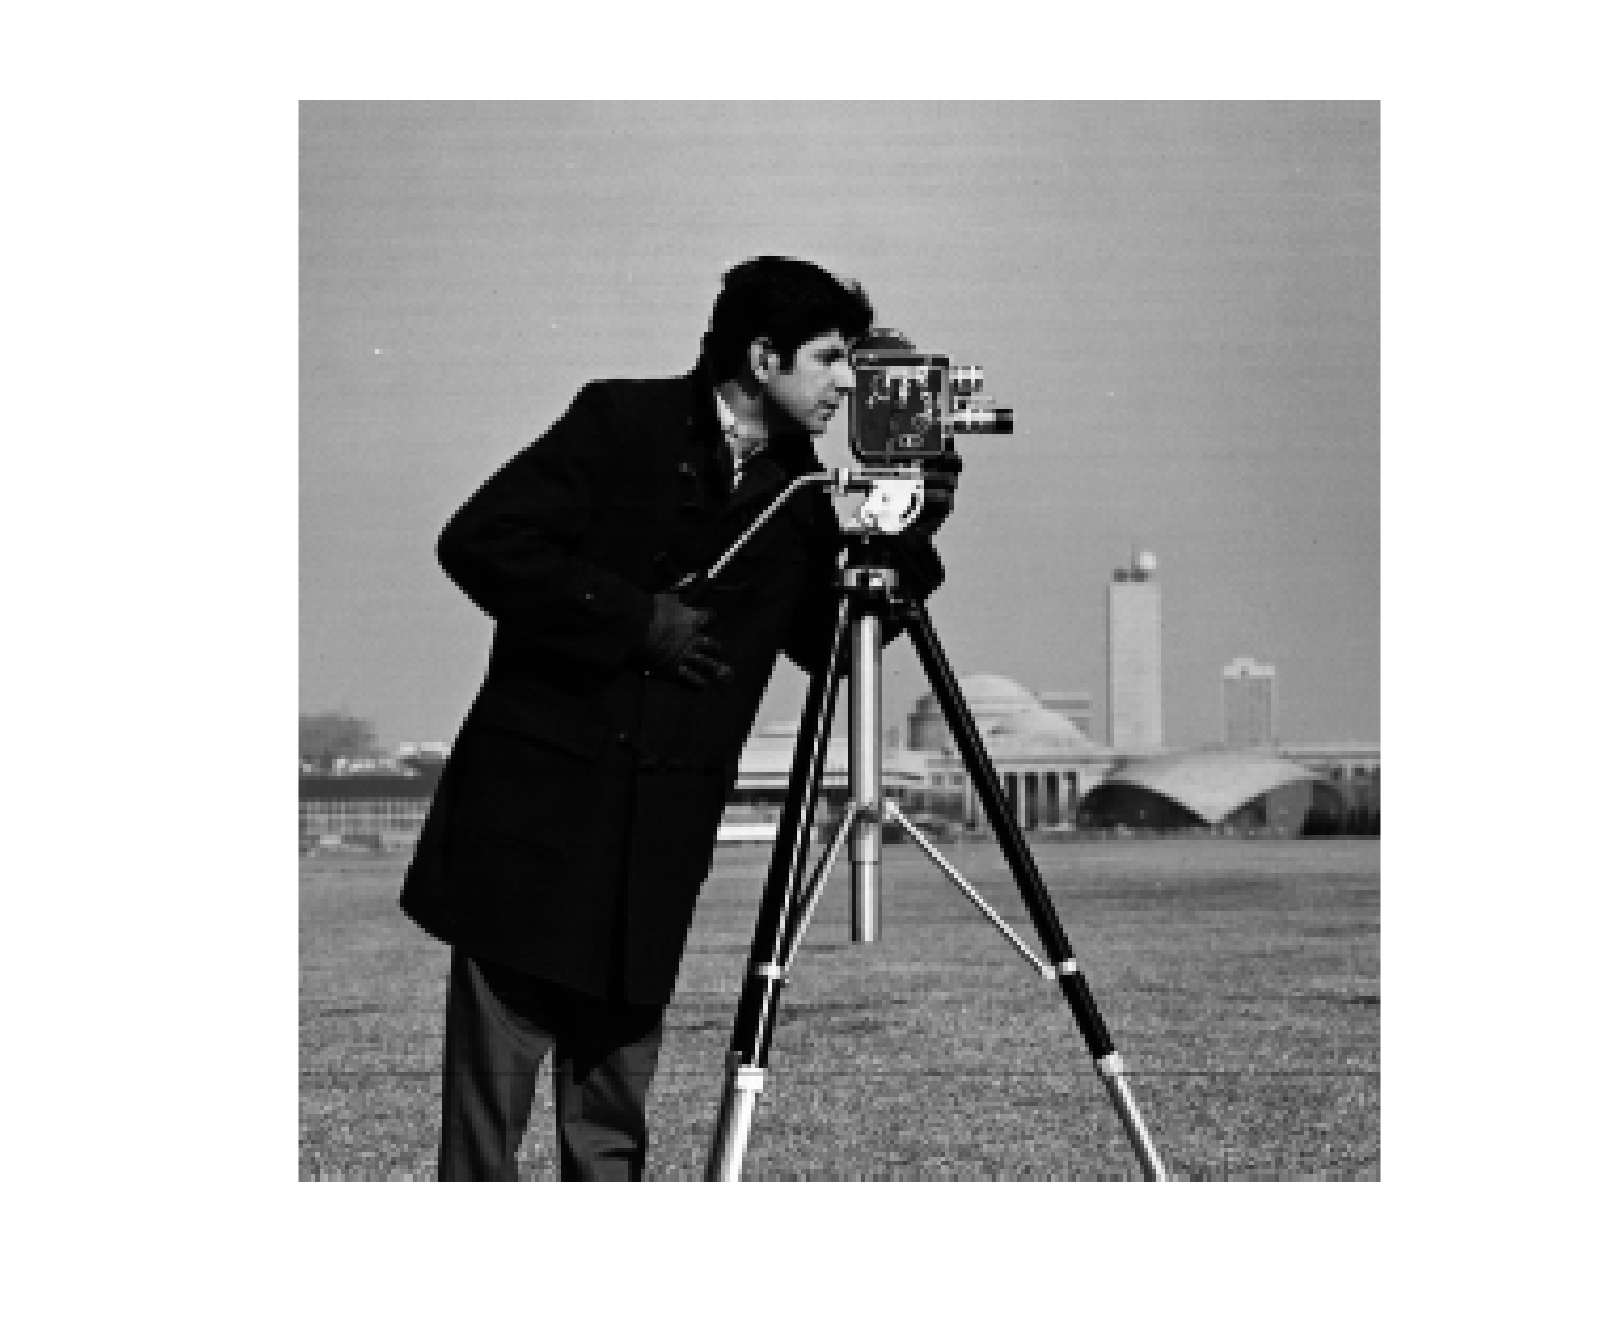

cameraman = imread('Important_files/cameraman.tif');
pout = imread('Important_files/pout.tif');
mikki = imread('Important_files/Mikki1_crop_close.jpeg');

%img = rgb2gray(mikki);
img = pout;
%img = cameraman;

imshow(cameraman, []);

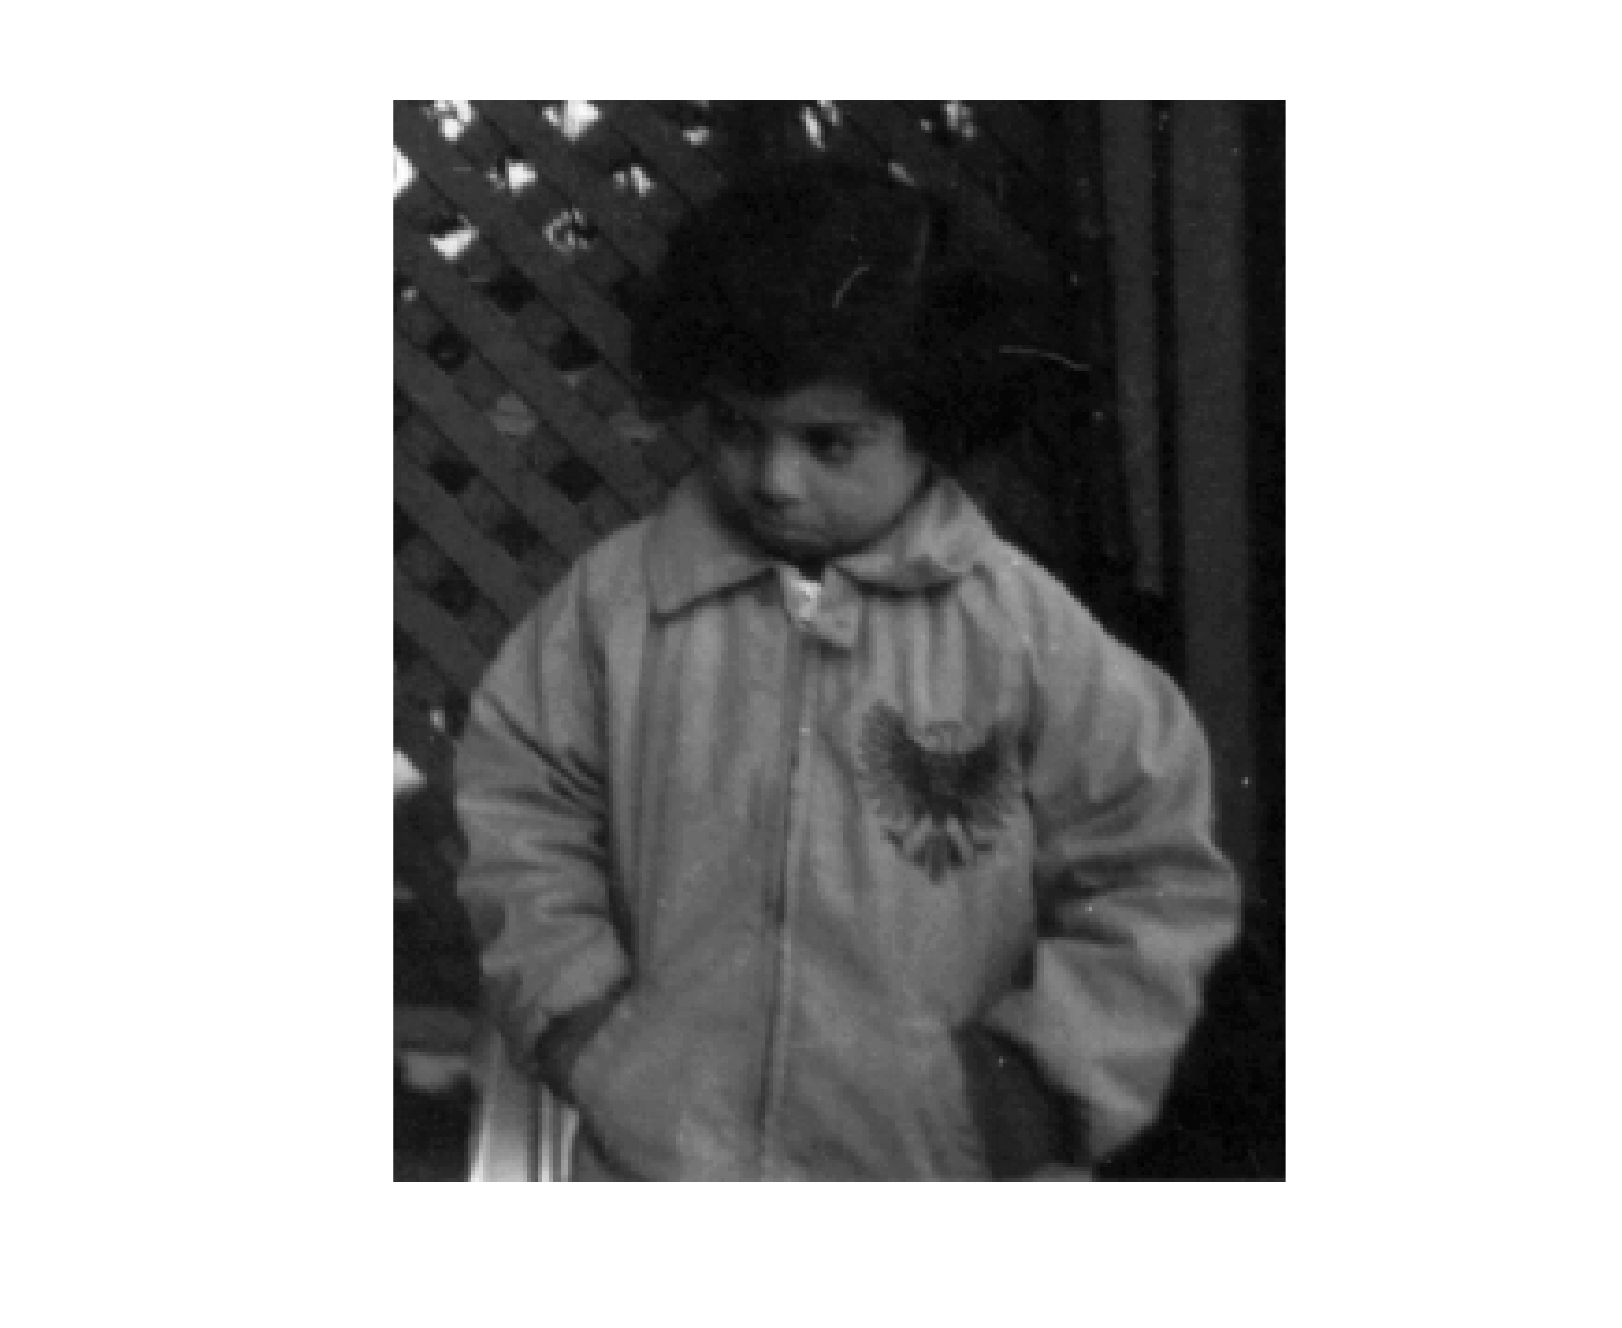

imshow(pout, []);

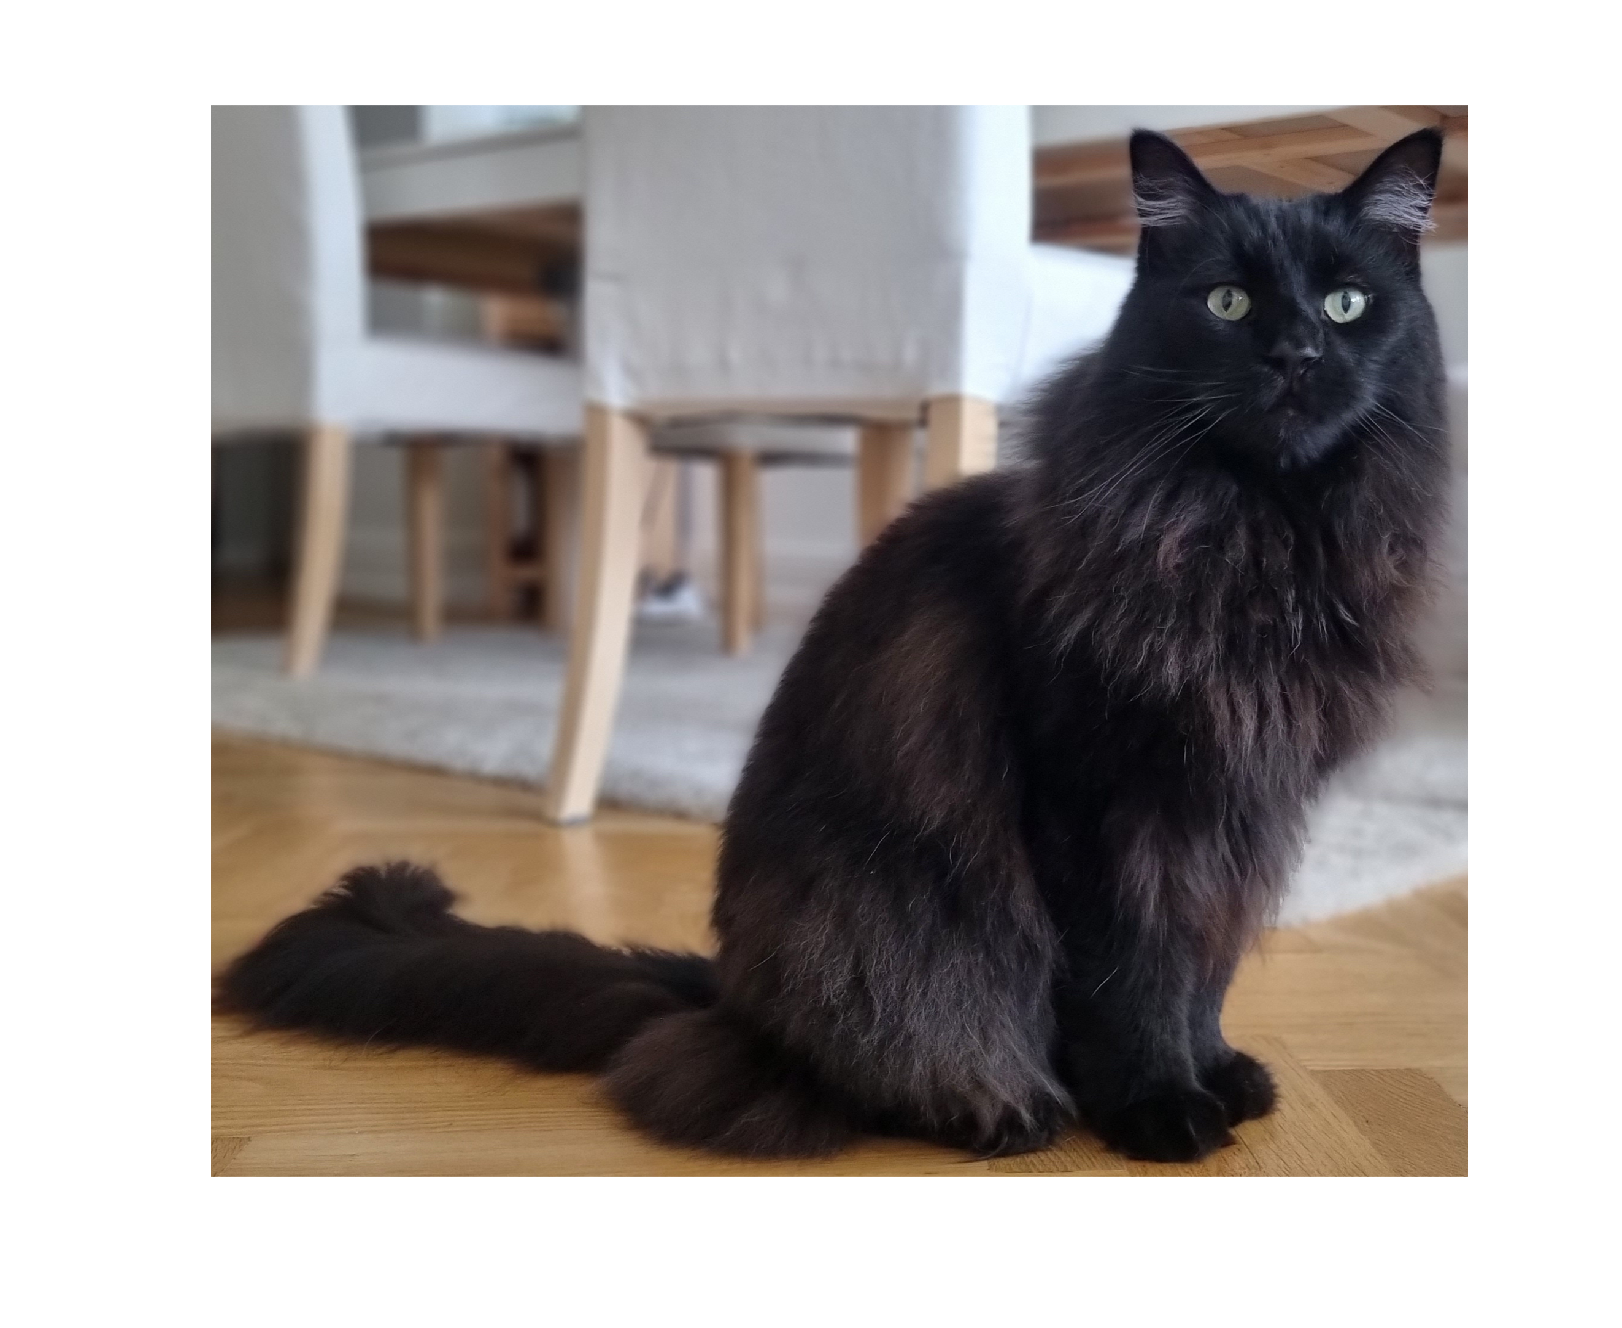

imshow(mikki, []);

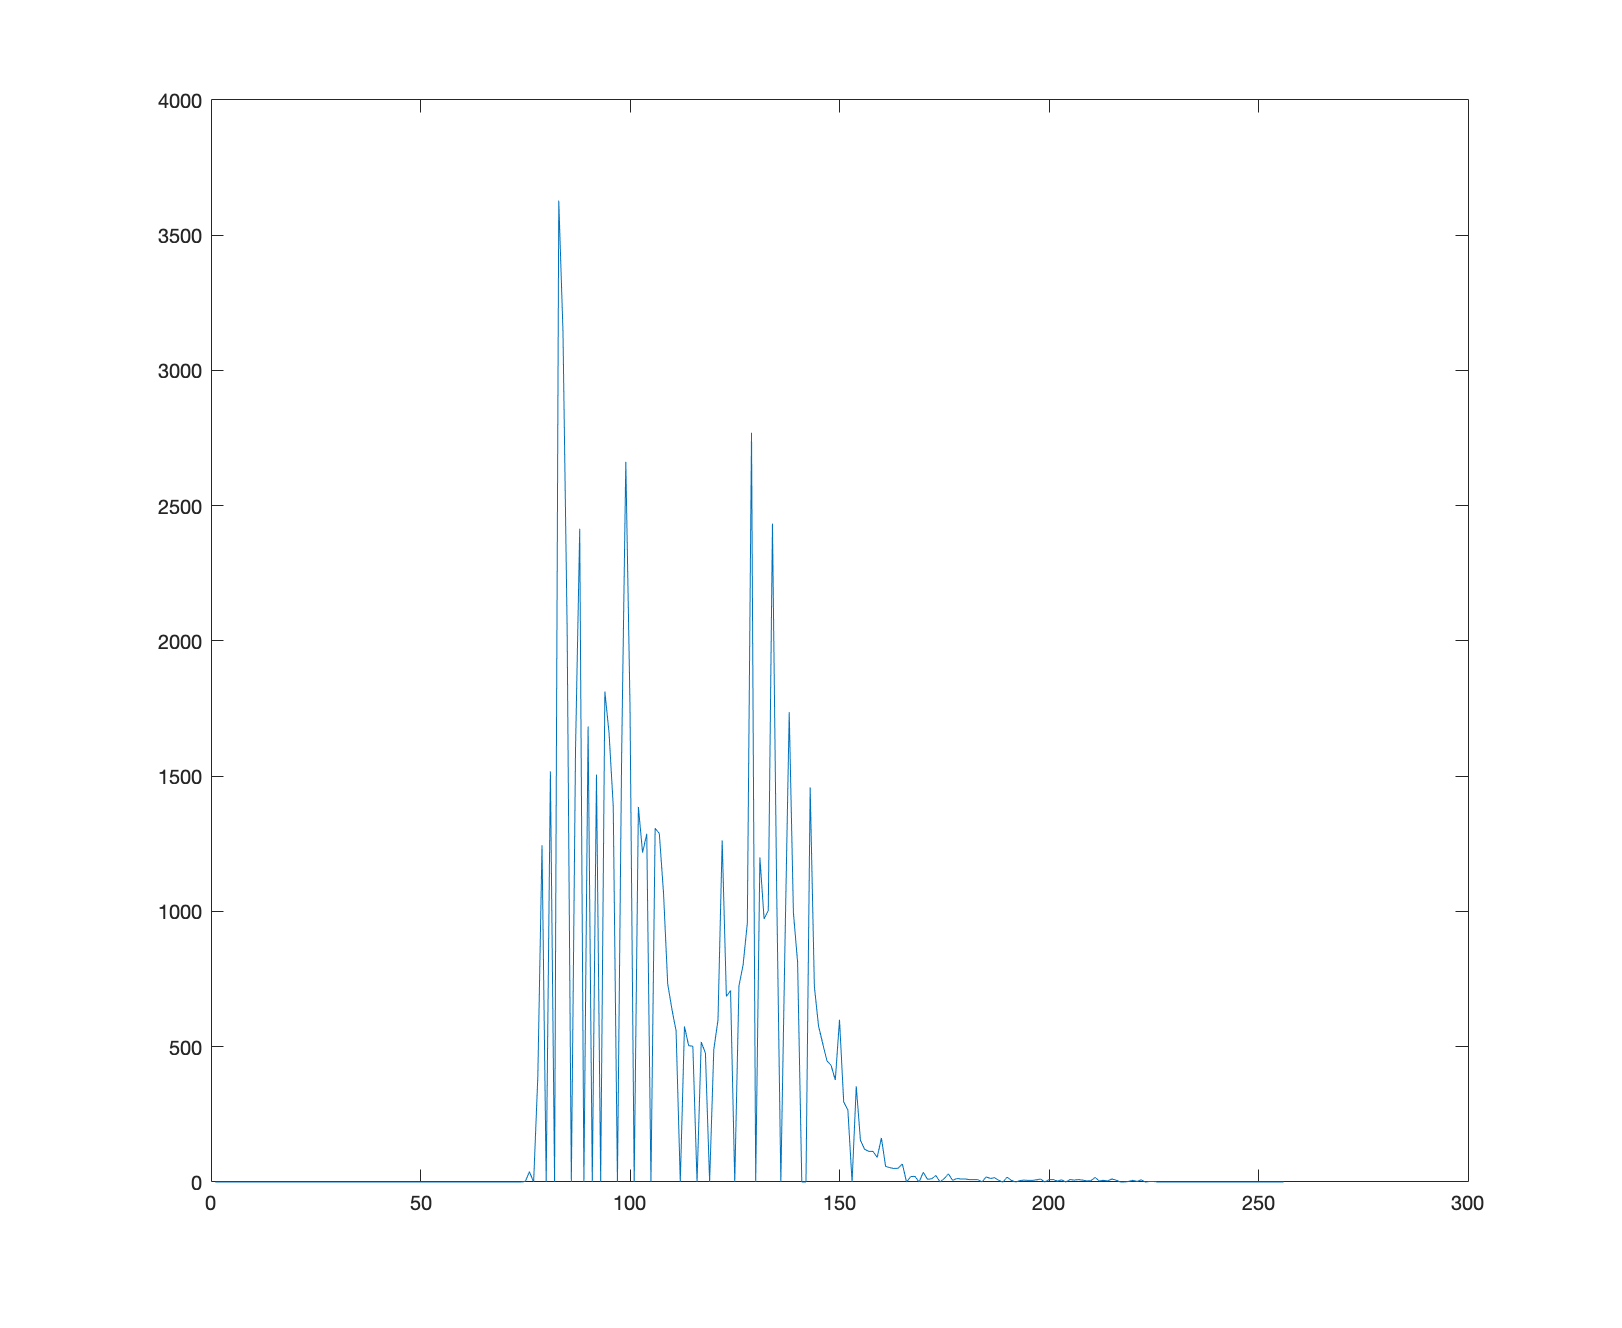


hist = imhist(img);
plot(hist);


[width, height] = size(img);

p = hist / (width * height);
p(p==0) = [];
logged_p = log2(p);

%logged_p(isnan(logged_p))=0;

H = - sum(p .* logged_p);

H = 5.7599

hist = [2,2,3,4,1,2,1,1];
p = hist / 16;

H = - sum(p.*log2(p));

H = 2.8278

(4*2+3*2+2*3+2*3+2*3+1*4+1*5+1*5)/16

ans = 2.8750

x = [1,2,3,4,5,6,7,8];
N = [2,2,3,4,1,2,1,1]/16;
huffmandict(x,N) 

ans = 8×2 cell array
    {[1]}    {1×3 double}
    {[2]}    {1×3 double}
    {[3]}    {1×2 double}
    {[4]}    {1×2 double}
    {[5]}    {1×5 double}
    {[6]}    {1×3 double}
    {[7]}    {1×5 double}
    {[8]}    {1×4 double}


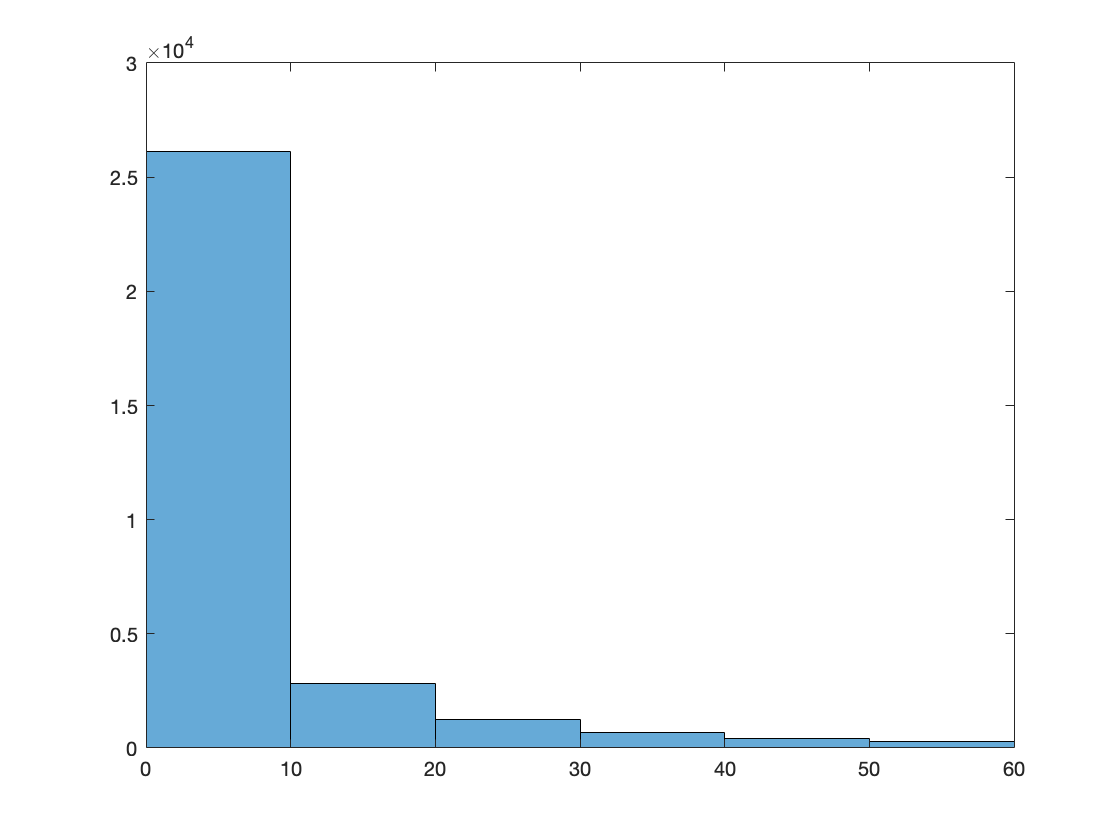

image = imread('Important_files/cameraman.tif');

load('DFTcoefs.mat');
[c, s] = wavedec2(image, 5, 'Haar');
img_hist = histogram(c);
xlim([0,60])

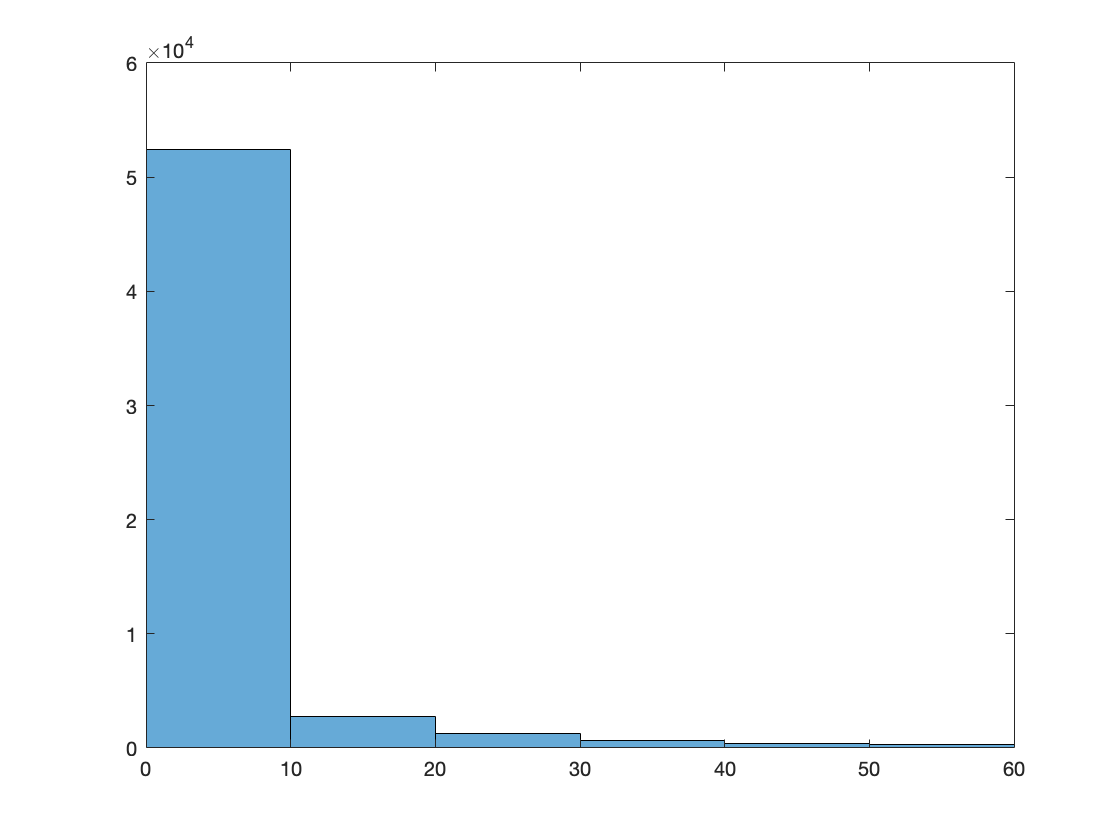

img_hist_mod = histogram(coefs);
xlim([0,60]);

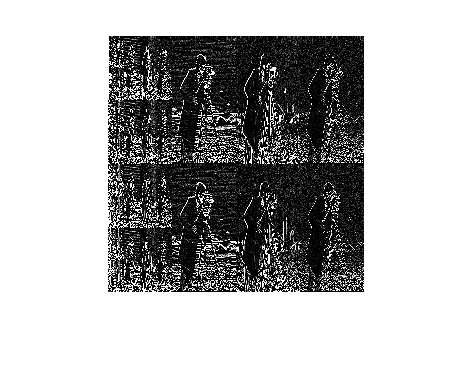


I_FWT = reshape(c, 256, 256); 
imshow(I_FWT, [0 10]);

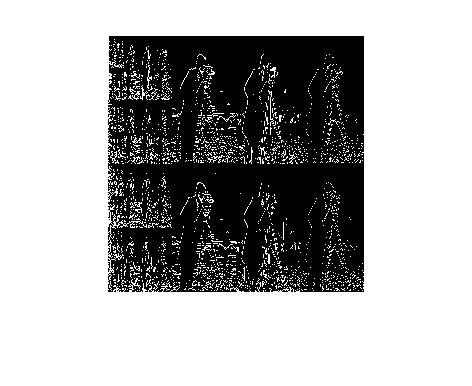

I_FWT_mod = reshape(coefs, 256, 256); 
imshow(I_FWT_mod, [0 10]);

figure
I_hist = imhist(I_FWT);
I_hist_mod = imhist(I_FWT_mod);

p = I_hist / (256^2);
p(p==0) = [];
logged_p = log2(p);
H = - sum(p .* logged_p)

H = 1.4538


p_mod = I_hist_mod / (256^2);
p_mod(p_mod==0) = [];
logged_p_mod = log2(p_mod);
H_mod = - sum(p_mod .* logged_p_mod)

H_mod = 0.4740